# Call and Provide ROS 2 Services

ROS supports two main communication mechanisms: topics and services. Topics have publishers and subscribers and are used for sending and receiving messages (see [Exchange Data with ROS 2 Publishers and Subscribers](docid:ros_ug#mw_56920b2c-f2f6-4d6c-a7d6-97877266558d)). *Services*, on the other hand, implement a tighter coupling by allowing request-response communication. A *service client* sends a request message to a *service server* and waits for a response. The server will use the data in the request to construct a response message and sends it back to the client. Each service has a type that determines the structure of the request and response messages.

This service communication has the following characteristics:

- A service request (or service call) is used for one-to-one communication. A single node will initiate the request and only one node will receive the request and send back a response.

- A service client and a service server are tightly coupled when a service call is executed. The server needs to exist at the time of the service call and once the request is sent, the client will block until a response is received.

The concept of services is illustrated in the following image:

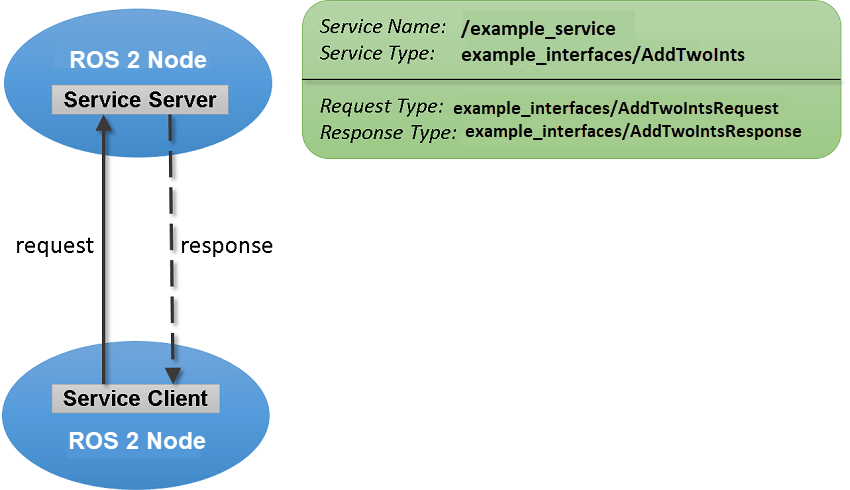

This example shows you how to set up service servers to advertise a service to the ROS network. In addition, you will learn how to use service clients to call the server and receive a response.

Prerequisites: [Get Started with ROS 2](docid:ros_ug#mw_9aa75390-b989-436d-94b2-8125909cd238),  [Connect to a ROS 2 Network](docid:ros_ug#mw_ef69ae07-7234-49b7-b384-86c479d401fd),  [Exchange Data with ROS 2 Publishers and Subscribers](docid:ros_ug#mw_56920b2c-f2f6-4d6c-a7d6-97877266558d)

## Create Service Server

Before examining service concepts, create the sample ROS 2 network with three nodes to simulate a realistic network.

node_1 = ros2node("node_1");
node_2 = ros2node("node_2");
node_3 = ros2node("node_3");

Suppose you want to make a simple service server that displays *"A service client is calling"* when you call the service. Create the service using the [`ros2svcserver`](docid:ros_ref#mw_f27ac58d-4272-4c53-b2a0-0e686bc24407) command. Specify the service name, the service message type and the node to attach the server. Also define the callback function as `exampleHelperROSEmptyCallback`. Callback functions for service servers have a very specific signature. For details, see the documentation of [`ros2svcserver`](docid:ros_ref#mw_f27ac58d-4272-4c53-b2a0-0e686bc24407).

testserver = ros2svcserver(node_1,"/service_example","std_srvs/Empty",@exampleHelperROS2EmptyCallback)

You can see your new service, `/test`, when you list all services in the ROS network.

ros2("service","list");

## Create Service Client

Use service clients to request information from a ROS 2 service server. To create a client, use [`ros2svcclient`](docid:ros_ref#mw_05d835a3-3d0f-4b87-a628-e1fc85959a5f) with the service name as the argument.

Create a service client for the `/test` service that we just created and attach it to a different node.

testclient = ros2svcclient(node_2,"/service_example","std_srvs/Empty")

Create an empty request message for the service. Use the [`ros2message`](docid:ros_ref#mw_31f67c3e-7acf-4d8e-85bb-33d976da2f28) function and pass the client as the first argument. This will create a service request function that has the message type that is specified by the service.

testreq = ros2message(testclient)

Ensure that the service is connected to the client, waiting for them to connect if necessary.

waitForServer(testclient,"Timeout",3)

When you want to get a response from the server, use the [`call`](docid:ros_ref.buqbgqj) function, which calls the service server and returns a response. The service server you created before will return an empty response. In addition, it will call the `exampleHelperROSEmptyCallback` function and displays the string *"A service client is calling"*. You can also define a `Timeout` parameter, which indicates how long the client should wait for a response. `status` and `statustext` outputs provide additional information about the status of the response. 

testresp = call(testclient,testreq,"Timeout",3)

If the call function above fails, it will error. Instead of an error, if you would prefer to react to a call failure using conditionals, return the status and statustext outputs from the call function. The status output indicates if the call succeeded, while statustext provides additional information. Similar outputs can be returned from waitForServer.

numCallFailures = 0;
[testresp,status,statustext] = call(testclient,testreq,"Timeout",3);
if ~status
    numCallFailures = numCallFailues + 1;
    fprintf("Call failure number %d. Error cause: %s\n",numCallFailures,statustext)
else
    disp(testresp)
end

## Create a Service for Adding Two Numbers

Up to now, the service server has not done any meaningful work, but you can use services for computations and data manipulation. Create a service that adds two integers.

There is an existing service type, `example_interfaces/AddTwoInts`, that we can use for this task. You can inspect the structure of the request and response messages by calling `ros2` `msg` `show`. The request contains two integers, `a` and `b`, and the response contains their addition in `sum`.

ros2 msg show example_interfaces/AddTwoIntsRequest
ros2 msg show example_interfaces/AddTwoIntsResponse

Create the service server with this message type and a callback function that calculates the addition. For your convenience, the `exampleHelperROS2SumCallback` function already implements this calculation. Specify the function as a callback.

% sumserver = ros2svcserver(...)

To call the service server, you have to create a service client. Note that this client can be created anywhere in the ROS 2 network. For the purposes of this example, we will create a client for the `/sum` service in MATLAB. Then we will wait to ensure the client has connected to the server.

% sumclient = ros2svcclient(...)
% waitForServer(...);

Create the request message. You can define the two integers, `a` and `b`, which are added together when you use the [`call`](docid:ros_ref.buqbgqj) command.

% sumreq = ros2message(...)

The expectation is that the sum of these two numbers will be 3. To call the service, use the following command. The service response message will contain a `sum` property, which stores the addition of `a` and `b`. 

% sumresp = call(...)

## Shut Down ROS 2 Network

Remove the sample nodes and service servers from the ROS 2 network.

clear("node_1");
clear("node_2");
clear("node_3");

*Copyright 2021 The MathWorks, Inc.*